# Spiking Neural Network that Maps from Generalized to Cartesian Coordinates

# Overview

- Program for calculating forward kinematics.

- Compare with original and show more resilient.

- Incorporate accuracy and lag calculations into design program, i.e. give joint twists and number of sensory neurons for each one, calculate everything else for me. 

- Make design process as automatic as possible. 

- Try out on different legs. 

# Methods

# Introduction

The kinematics of the bug include the lengths of the tibia, femur, and thorax.

- *R* is the maximum expected membrance voltage above rest, 20 mV. 

- *E* is the reversal potential above the resting membrane potential, 70 mV.

- $l_{\textrm{ti}\;}$ is the tibia length, 10 cm.

- $l_{\textrm{fe}}$ is the femur length, 10 cm.

- $l_{\textrm{th}}$ is the thorax, positioned at 0. 

## 3.1 Initial Variables

clear
width = [5,15,25,35,45,55]

width =      5    15    25    35    45    55


I =      1     0     0
     0     1     0
     0     0     1


g_T_l2 =          0
    0.2000
         0


g_foot_thorax_zero =     1.0000         0         0         0
         0    1.0000         0    0.2000
         0         0    1.0000         0
         0         0         0    1.0000


zeta1 =          0
         0
         0
         0
    0.6018
    0.7986


zeta2 =      0
     0
     0
    -1
     0
     0


zeta3 =          0
         0
    0.1000
   -1.0000
         0
         0


omega_skew1 =          0   -0.7986    0.6018
    0.7986         0         0
   -0.6018         0         0


omega_skew2 =      0     0     0
     0     0     1
     0    -1     0


omega_skew3 =      0     0     0
     0     0     1
     0    -1     0


output = output(:,:,1,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,2,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,3,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,4,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,5,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,1,2) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN

100
200
300
400
500
600
700
800
900
1000
1100
1200
1300
1400
1500
1600
1700
1800
1900
2000
2100
2200
2300
2400
2500
2600
2700
2800
2900
3000
3100
3200
3300
3400
3500
3600
3700
3800
3900
4000
4100
4200
4300
4400
4500
4600
4700
4800
4900
5000
5100
5200
5300
5400
5500
5600
5700
5800
5900
6000
6100
6200
6300
6400
6500
6600
6700
6800
6900
7000
7100
7200
7300
7400
7500
7600
7700
7800
7900
8000
8100
8200
8300
8400
8500
8600
8700
8800
8900
9000
9100
9200
9300
9400
9500
9600
9700
9800
9900
10000
10100
10200
10300
10400
10500
10600
10700
10800
10900
11000
11100
11200
11300
11400
11500
11600
11700
11800
11900
12000
12100
12200
12300
12400
12500


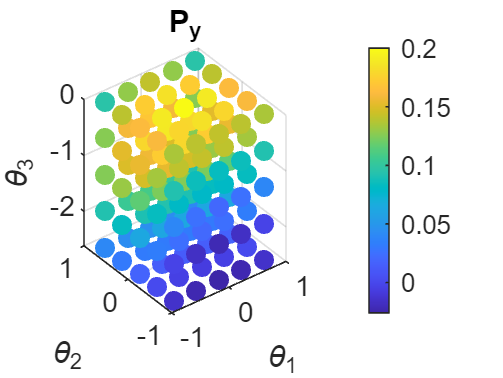

I =      1     0     0
     0     1     0
     0     0     1


g_T_l2 =          0
    0.2000
         0


g_foot_thorax_zero =     1.0000         0         0         0
         0    1.0000         0    0.2000
         0         0    1.0000         0
         0         0         0    1.0000


zeta1 =          0
         0
         0
         0
    0.6018
    0.7986


zeta2 =      0
     0
     0
    -1
     0
     0


zeta3 =          0
         0
    0.1000
   -1.0000
         0
         0


omega_skew1 =          0   -0.7986    0.6018
    0.7986         0         0
   -0.6018         0         0


omega_skew2 =      0     0     0
     0     0     1
     0    -1     0


omega_skew3 =      0     0     0
     0     0     1
     0    -1     0


output = output(:,:,1,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,2,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,3,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,4,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,5,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,1,2) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN

1.250000e+01
25
3.750000e+01
50
6.250000e+01
75
8.750000e+01
100
1.125000e+02
125
1.375000e+02
150
1.625000e+02
175
1.875000e+02
200
2.125000e+02
225
2.375000e+02
250
2.625000e+02
275
2.875000e+02
300
3.125000e+02
325
3.375000e+02
350
3.625000e+02
375
3.875000e+02
400
4.125000e+02
425
4.375000e+02
450
4.625000e+02
475
4.875000e+02
500
5.125000e+02
525
5.375000e+02
550
5.625000e+02
575
5.875000e+02
600
6.125000e+02
625
6.375000e+02
650
6.625000e+02
675
6.875000e+02
700
7.125000e+02
725
7.375000e+02
750
7.625000e+02
775
7.875000e+02
800
8.125000e+02
825
8.375000e+02
850
8.625000e+02
875
8.875000e+02
900
9.125000e+02
925
9.375000e+02
950
9.625000e+02
975
9.875000e+02
1000
1.012500e+03
1025
1.037500e+03
1050
1.062500e+03
1075
1.087500e+03
1100
1.112500e+03
1125
1.137500e+03
1150
1.162500e+03
1175
1.187500e+03
1200
1.212500e+03
1225
1.237500e+03
1250
1.262500e+03
1275
1.287500e+03
1300
1.312500e+03
1325
1.337500e+03
1350
1.362500e+03
1375
1.387500e+03
1400
1.412500e+03
1425
1.437500e+03
145

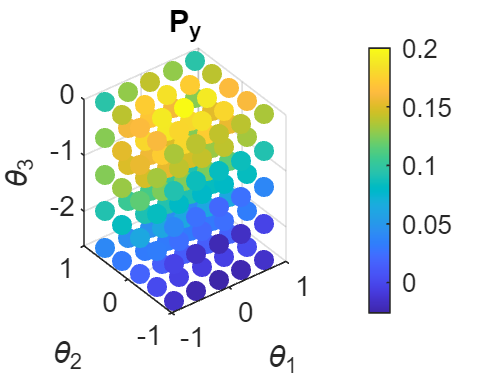

I =      1     0     0
     0     1     0
     0     0     1


g_T_l2 =          0
    0.2000
         0


g_foot_thorax_zero =     1.0000         0         0         0
         0    1.0000         0    0.2000
         0         0    1.0000         0
         0         0         0    1.0000


zeta1 =          0
         0
         0
         0
    0.6018
    0.7986


zeta2 =      0
     0
     0
    -1
     0
     0


zeta3 =          0
         0
    0.1000
   -1.0000
         0
         0


omega_skew1 =          0   -0.7986    0.6018
    0.7986         0         0
   -0.6018         0         0


omega_skew2 =      0     0     0
     0     0     1
     0    -1     0


omega_skew3 =      0     0     0
     0     0     1
     0    -1     0


output = output(:,:,1,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,2,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,3,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,4,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,5,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,1,2) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN

3.703704e+00
7.407407e+00
1.111111e+01
1.481481e+01
1.851852e+01
2.222222e+01
2.592593e+01
2.962963e+01
3.333333e+01
3.703704e+01
4.074074e+01
4.444444e+01
4.814815e+01
5.185185e+01
5.555556e+01
5.925926e+01
6.296296e+01
6.666667e+01
7.037037e+01
7.407407e+01
7.777778e+01
8.148148e+01
8.518519e+01
8.888889e+01
9.259259e+01
9.629630e+01
100
1.037037e+02
1.074074e+02
1.111111e+02
1.148148e+02
1.185185e+02
1.222222e+02
1.259259e+02
1.296296e+02
1.333333e+02
1.370370e+02
1.407407e+02
1.444444e+02
1.481481e+02
1.518519e+02
1.555556e+02
1.592593e+02
1.629630e+02
1.666667e+02
1.703704e+02
1.740741e+02
1.777778e+02
1.814815e+02
1.851852e+02
1.888889e+02
1.925926e+02
1.962963e+02
200
2.037037e+02
2.074074e+02
2.111111e+02
2.148148e+02
2.185185e+02
2.222222e+02
2.259259e+02
2.296296e+02
2.333333e+02
2.370370e+02
2.407407e+02
2.444444e+02
2.481481e+02
2.518519e+02
2.555556e+02
2.592593e+02
2.629630e+02
2.666667e+02
2.703704e+02
2.740741e+02
2.777778e+02
2.814815e+02
2.851852e+02
2.888889e+02
2.92

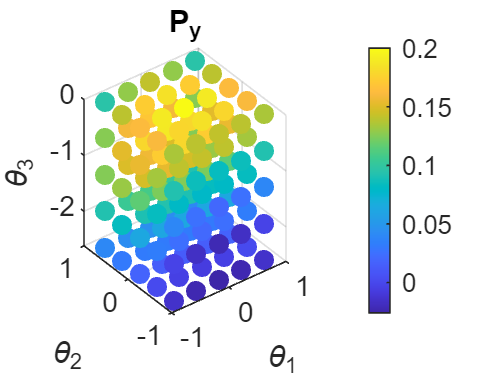

I =      1     0     0
     0     1     0
     0     0     1


g_T_l2 =          0
    0.2000
         0


g_foot_thorax_zero =     1.0000         0         0         0
         0    1.0000         0    0.2000
         0         0    1.0000         0
         0         0         0    1.0000


zeta1 =          0
         0
         0
         0
    0.6018
    0.7986


zeta2 = 6×1
     0
     0
     0
    -1
     0
     0


zeta3 = 6×1
         0
         0
    0.1000
   -1.0000
         0
         0


omega_skew1 = 3×3
         0   -0.7986    0.6018
    0.7986         0         0
   -0.6018         0         0


omega_skew2 = 3×3
     0     0     0
     0     0     1
     0    -1     0


omega_skew3 = 3×3
     0     0     0
     0     0     1
     0    -1     0


output = output(:,:,1,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,2,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,3,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,4,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,5,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,1,2) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN

1.562500e+00
3.125000e+00
4.687500e+00
6.250000e+00
7.812500e+00
9.375000e+00
1.093750e+01
1.250000e+01
1.406250e+01
1.562500e+01
1.718750e+01
1.875000e+01
2.031250e+01
2.187500e+01
2.343750e+01
25
2.656250e+01
2.812500e+01
2.968750e+01
3.125000e+01
3.281250e+01
3.437500e+01
3.593750e+01
3.750000e+01
3.906250e+01
4.062500e+01
4.218750e+01
4.375000e+01
4.531250e+01
4.687500e+01
4.843750e+01
50
5.156250e+01
5.312500e+01
5.468750e+01
5.625000e+01
5.781250e+01
5.937500e+01
6.093750e+01
6.250000e+01
6.406250e+01
6.562500e+01
6.718750e+01
6.875000e+01
7.031250e+01
7.187500e+01
7.343750e+01
75
7.656250e+01
7.812500e+01
7.968750e+01
8.125000e+01
8.281250e+01
8.437500e+01
8.593750e+01
8.750000e+01
8.906250e+01
9.062500e+01
9.218750e+01
9.375000e+01
9.531250e+01
9.687500e+01
9.843750e+01
100
1.015625e+02
1.031250e+02
1.046875e+02
1.062500e+02
1.078125e+02
1.093750e+02
1.109375e+02
1.125000e+02
1.140625e+02
1.156250e+02
1.171875e+02
1.187500e+02
1.203125e+02
1.218750e+02
1.234375e+02
125
1.265625

I = 3×3
     1     0     0
     0     1     0
     0     0     1


g_T_l2 = 3×1
         0
    0.2000
         0


g_foot_thorax_zero = 4×4
    1.0000         0         0         0
         0    1.0000         0    0.2000
         0         0    1.0000         0
         0         0         0    1.0000


zeta1 = 6×1
         0
         0
         0
         0
    0.6018
    0.7986


zeta2 = 6×1
     0
     0
     0
    -1
     0
     0


zeta3 = 6×1
         0
         0
    0.1000
   -1.0000
         0
         0


omega_skew1 = 3×3
         0   -0.7986    0.6018
    0.7986         0         0
   -0.6018         0         0


omega_skew2 = 3×3
     0     0     0
     0     0     1
     0    -1     0


omega_skew3 = 3×3
     0     0     0
     0     0     1
     0    -1     0


output = output(:,:,1,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,2,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,3,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,4,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,5,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,1,2) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN

8.000000e-01
1.600000e+00
2.400000e+00
3.200000e+00
4
4.800000e+00
5.600000e+00
6.400000e+00
7.200000e+00
8
8.800000e+00
9.600000e+00
1.040000e+01
1.120000e+01
12
1.280000e+01
1.360000e+01
1.440000e+01
1.520000e+01
16
1.680000e+01
1.760000e+01
1.840000e+01
1.920000e+01
20
2.080000e+01
2.160000e+01
2.240000e+01
2.320000e+01
24
2.480000e+01
2.560000e+01
2.640000e+01
2.720000e+01
28
2.880000e+01
2.960000e+01
3.040000e+01
3.120000e+01
32
3.280000e+01
3.360000e+01
3.440000e+01
3.520000e+01
36
3.680000e+01
3.760000e+01
3.840000e+01
3.920000e+01
40
4.080000e+01
4.160000e+01
4.240000e+01
4.320000e+01
44
4.480000e+01
4.560000e+01
4.640000e+01
4.720000e+01
48
4.880000e+01
4.960000e+01
5.040000e+01
5.120000e+01
52
5.280000e+01
5.360000e+01
5.440000e+01
5.520000e+01
56
5.680000e+01
5.760000e+01
5.840000e+01
5.920000e+01
60
6.080000e+01
6.160000e+01
6.240000e+01
6.320000e+01
64
6.480000e+01
6.560000e+01
6.640000e+01
6.720000e+01
68
6.880000e+01
6.960000e+01
7.040000e+01
7.120000e+01
72
7.280000e+01

I = 3×3
     1     0     0
     0     1     0
     0     0     1


g_T_l2 = 3×1
         0
    0.2000
         0


g_foot_thorax_zero = 4×4
    1.0000         0         0         0
         0    1.0000         0    0.2000
         0         0    1.0000         0
         0         0         0    1.0000


zeta1 = 6×1
         0
         0
         0
         0
    0.6018
    0.7986


zeta2 = 6×1
     0
     0
     0
    -1
     0
     0


zeta3 = 6×1
         0
         0
    0.1000
   -1.0000
         0
         0


omega_skew1 = 3×3
         0   -0.7986    0.6018
    0.7986         0         0
   -0.6018         0         0


omega_skew2 = 3×3
     0     0     0
     0     0     1
     0    -1     0


omega_skew3 = 3×3
     0     0     0
     0     0     1
     0    -1     0


output = output(:,:,1,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,2,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,3,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,4,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,5,1) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN


output(:,:,1,2) =

   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN

4.629630e-01
9.259259e-01
1.388889e+00
1.851852e+00
2.314815e+00
2.777778e+00
3.240741e+00
3.703704e+00
4.166667e+00
4.629630e+00
5.092593e+00
5.555556e+00
6.018519e+00
6.481481e+00
6.944444e+00
7.407407e+00
7.870370e+00
8.333333e+00
8.796296e+00
9.259259e+00
9.722222e+00
1.018519e+01
1.064815e+01
1.111111e+01
1.157407e+01
1.203704e+01
1.250000e+01
1.296296e+01
1.342593e+01
1.388889e+01
1.435185e+01
1.481481e+01
1.527778e+01
1.574074e+01
1.620370e+01
1.666667e+01
1.712963e+01
1.759259e+01
1.805556e+01
1.851852e+01
1.898148e+01
1.944444e+01
1.990741e+01
2.037037e+01
2.083333e+01
2.129630e+01
2.175926e+01
2.222222e+01
2.268519e+01
2.314815e+01
2.361111e+01
2.407407e+01
2.453704e+01
25
2.546296e+01
2.592593e+01
2.638889e+01
2.685185e+01
2.731481e+01
2.777778e+01
2.824074e+01
2.870370e+01
2.916667e+01
2.962963e+01
3.009259e+01
3.055556e+01
3.101852e+01
3.148148e+01
3.194444e+01
3.240741e+01
3.287037e+01
3.333333e+01
3.379630e+01
3.425926e+01
3.472222e+01
3.518519e+01
3.564815e+01
3.611111e

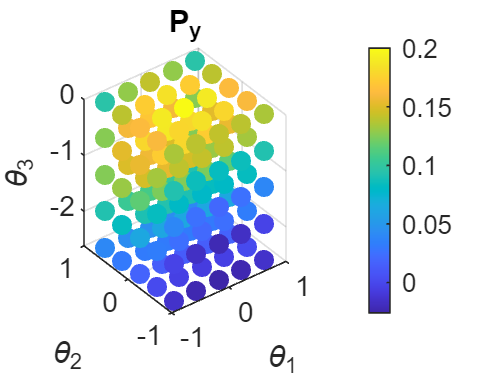

for n=1:length(width)

    R = 20; % [mV]
    Ein = -10;
    Eex = 70; % [mV]
    
    
    l_ti = 0.10; % tibia length = 10 cm
    l_fe = 0.10; % femur length = 10 cm
    l_th = 0; % thorax at 0

Table 2 Cruse, H. et al. - angle value describing position of rotational axis of th-coxa: middle leg 

- $\alpha \;$ is the protraction/retraction angle around the thorax - coxa

- $\beta \;$ is the levation/depression angle around the coxa-trochanter

- $\gamma \;$ is the flexion/extension angle around the femur - tibia

bell_1 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell1func = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell2func = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell3func = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


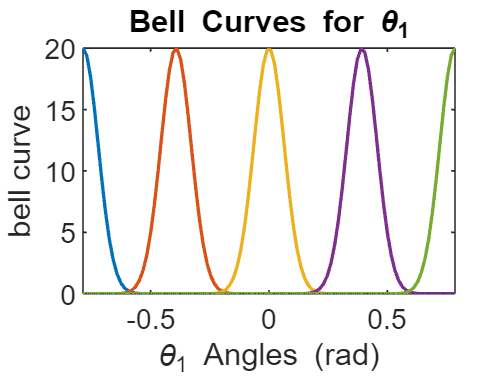

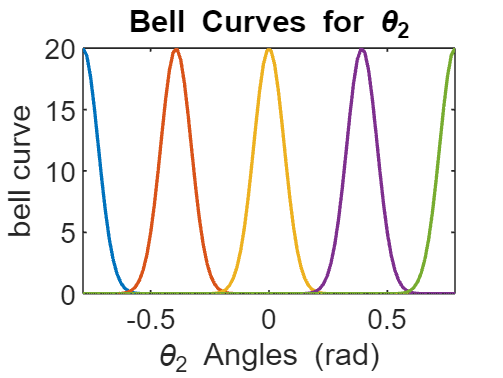

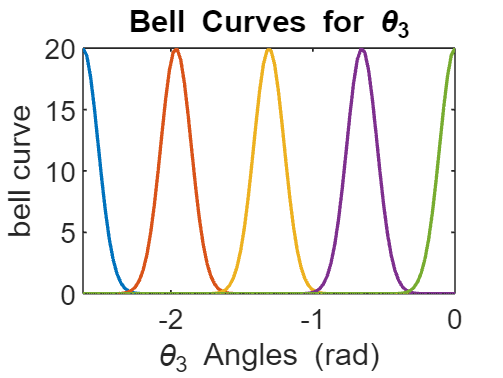

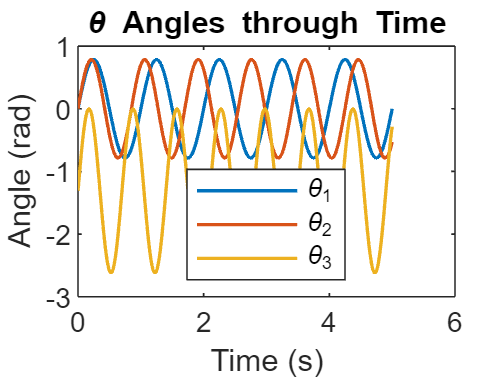

bell_1 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell1func = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell2func = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell3func = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


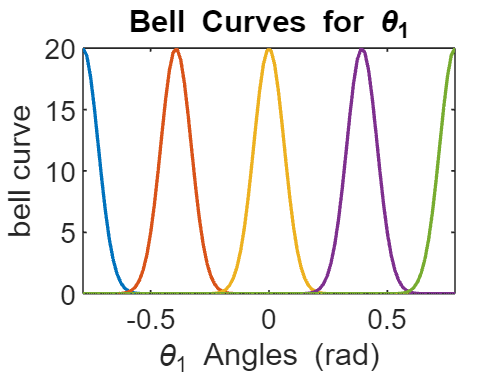

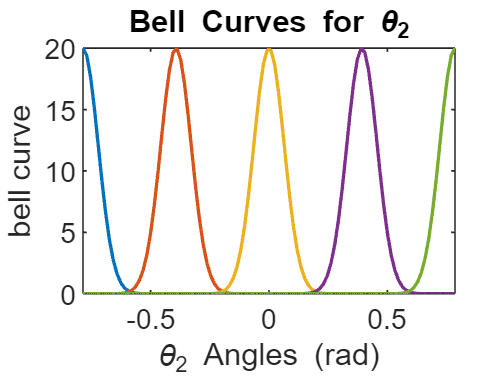

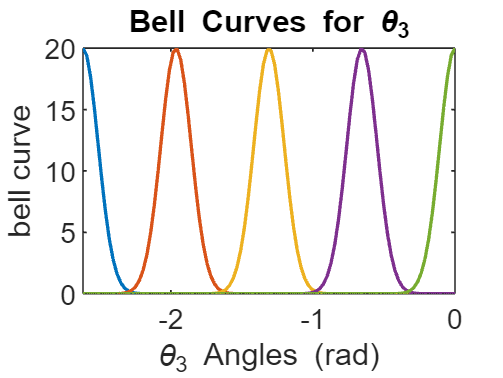

bell_1 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell1func = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell2func = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3 =    20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058    8.6026    6.0500    4.0022    2.4903    1.4575    0.8024    0.4155    0.2024    0.0927    0.0400    0.0162    0.0062    0.0022    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000

bell3func = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


bell_1 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell1func = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell2func = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell3func = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


bell_1 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell1func = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell2func = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell3func = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


bell_1 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell1func = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell2func = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3 = 5×100
   20.0000   19.3971   17.6952   15.1841   12.2556    9.3046    6.6446    4.4633    2.8200    1.6760    0.9369    0.4926    0.2437    0.1134    0.0496    0.0204    0.0079    0.0029    0.0010    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0013    0.0037    0.0101    0.0256    0.0613    0.1380    0.2922    0.5819    1.0898    1.9198    3.1812    4.9585    7.2697   10.0253   13.0044   15.8671   18.2104   19.6586   19.9618   19.0660   17.1290   14.4750   11.5058
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

bell3func = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


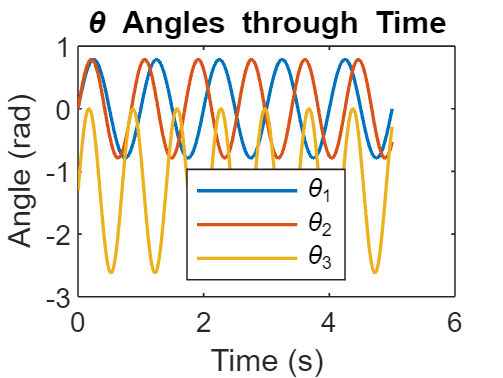

    theta1 = linspace(deg2rad(-45),deg2rad(45),5); % alpha in paper above --> can change 5 to 1
    theta2 = linspace(deg2rad(-45),deg2rad(45),5); % beta in paper above
    theta3 = linspace(deg2rad(-150),0,5); % gamma in paper above

## 3.2 Transformation from the Thorax frame to the End Effector

Describes the transformation from the thorax frame to the end effector.

### Step 1. Define the Zero Configuration. 

Frame in the zero configuration. 

bell_1new =    20.0000   19.9898   19.9592   19.9084   19.8374   19.7465   19.6360   19.5062   19.3576   19.1904   19.0053   18.8028   18.5834   18.3479   18.0969   17.8312   17.5514   17.2584   16.9530   16.6360   16.3083   15.9707   15.6242   15.2696   14.9078   14.5398   14.1664   13.7885   13.4069   13.0227   12.6366   12.2494   11.8620   11.4751   11.0895   10.7059   10.3251    9.9476    9.5742    9.2054    8.8418    8.4839    8.1321    7.7870    7.4490    7.1183    6.7954    6.4806    6.1740    5.8759
   14.6323   14.9989   15.3589   15.7116   16.0560   16.3911   16.7163   17.0304   17.3328   17.6226   17.8990   18.1611   18.4083   18.6398   18.8550   19.0532   19.2339   19.3965   19.5405   19.6655   19.7711   19.8570   19.9230   19.9688   19.9943   19.9994   19.9841   19.9484   19.8925   19.8166   19.7207   19.6054   19.4708   19.3175   19.1458   18.9563   18.7495   18.5260   18.2866   18.0318   17.7625   17.4794   17.1832   16.8748   16.5550   16.2248   15.8849   15.5362   15.1

bell1funcnew = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2new =    20.0000   19.9898   19.9592   19.9084   19.8374   19.7465   19.6360   19.5062   19.3576   19.1904   19.0053   18.8028   18.5834   18.3479   18.0969   17.8312   17.5514   17.2584   16.9530   16.6360   16.3083   15.9707   15.6242   15.2696   14.9078   14.5398   14.1664   13.7885   13.4069   13.0227   12.6366   12.2494   11.8620   11.4751   11.0895   10.7059   10.3251    9.9476    9.5742    9.2054    8.8418    8.4839    8.1321    7.7870    7.4490    7.1183    6.7954    6.4806    6.1740    5.8759
   14.6323   14.9989   15.3589   15.7116   16.0560   16.3911   16.7163   17.0304   17.3328   17.6226   17.8990   18.1611   18.4083   18.6398   18.8550   19.0532   19.2339   19.3965   19.5405   19.6655   19.7711   19.8570   19.9230   19.9688   19.9943   19.9994   19.9841   19.9484   19.8925   19.8166   19.7207   19.6054   19.4708   19.3175   19.1458   18.9563   18.7495   18.5260   18.2866   18.0318   17.7625   17.4794   17.1832   16.8748   16.5550   16.2248   15.8849   15.5362   15.1

bell2funcnew = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3new =    20.0000   19.9898   19.9592   19.9084   19.8374   19.7465   19.6360   19.5062   19.3576   19.1904   19.0053   18.8028   18.5834   18.3479   18.0969   17.8312   17.5514   17.2584   16.9530   16.6360   16.3083   15.9707   15.6242   15.2696   14.9078   14.5398   14.1664   13.7885   13.4069   13.0227   12.6366   12.2494   11.8620   11.4751   11.0895   10.7059   10.3251    9.9476    9.5742    9.2054    8.8418    8.4839    8.1321    7.7870    7.4490    7.1183    6.7954    6.4806    6.1740    5.8759
   14.6323   14.9989   15.3589   15.7116   16.0560   16.3911   16.7163   17.0304   17.3328   17.6226   17.8990   18.1611   18.4083   18.6398   18.8550   19.0532   19.2339   19.3965   19.5405   19.6655   19.7711   19.8570   19.9230   19.9688   19.9943   19.9994   19.9841   19.9484   19.8925   19.8166   19.7207   19.6054   19.4708   19.3175   19.1458   18.9563   18.7495   18.5260   18.2866   18.0318   17.7625   17.4794   17.1832   16.8748   16.5550   16.2248   15.8849   15.5362   15.1

bell3funcnew = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


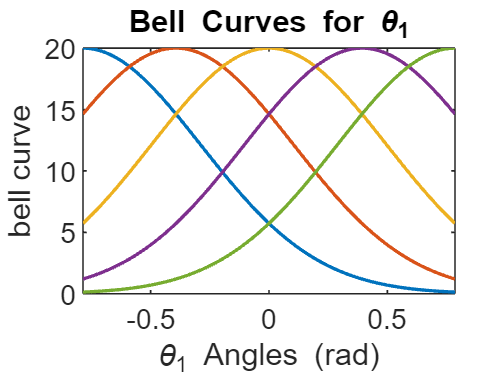

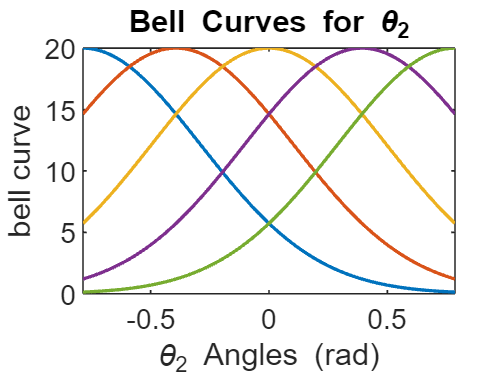

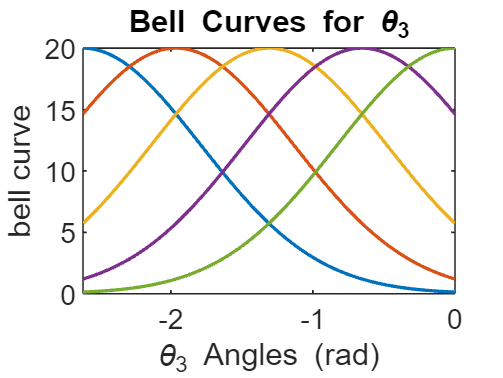

bell_1new =    20.0000   19.9694   19.8779   19.7264   19.5162   19.2492   18.9279   18.5550   18.1339   17.6682   17.1618   16.6190   16.0442   15.4419   14.8168   14.1736   13.5168   12.8511   12.1808   11.5102   10.8433   10.1838    9.5352    8.9006    8.2829    7.6844    7.1075    6.5537    6.0246    5.5213    5.0446    4.5950    4.1726    3.7775    3.4094    3.0677    2.7518    2.4609    2.1941    1.9502    1.7281    1.5266    1.3445    1.1805    1.0333    0.9017    0.7845    0.6804    0.5883    0.5072
    7.8321    8.4356    9.0578    9.6962   10.3478   11.0095   11.6777   12.3486   13.0181   13.6820   14.3358   14.9750   15.5948   16.1906   16.7579   17.2920   17.7886   18.2435   18.6529   19.0132   19.3212   19.5742   19.7699   19.9065   19.9828   19.9981   19.9522   19.8456   19.6793   19.4547   19.1739   18.8394   18.4541   18.0215   17.5452   17.0294   16.4781   15.8960   15.2876   14.6575   14.0105   13.3511   12.6838   12.0131   11.3430   10.6776   10.0205    9.3751    8.7

bell1funcnew = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2new =    20.0000   19.9694   19.8779   19.7264   19.5162   19.2492   18.9279   18.5550   18.1339   17.6682   17.1618   16.6190   16.0442   15.4419   14.8168   14.1736   13.5168   12.8511   12.1808   11.5102   10.8433   10.1838    9.5352    8.9006    8.2829    7.6844    7.1075    6.5537    6.0246    5.5213    5.0446    4.5950    4.1726    3.7775    3.4094    3.0677    2.7518    2.4609    2.1941    1.9502    1.7281    1.5266    1.3445    1.1805    1.0333    0.9017    0.7845    0.6804    0.5883    0.5072
    7.8321    8.4356    9.0578    9.6962   10.3478   11.0095   11.6777   12.3486   13.0181   13.6820   14.3358   14.9750   15.5948   16.1906   16.7579   17.2920   17.7886   18.2435   18.6529   19.0132   19.3212   19.5742   19.7699   19.9065   19.9828   19.9981   19.9522   19.8456   19.6793   19.4547   19.1739   18.8394   18.4541   18.0215   17.5452   17.0294   16.4781   15.8960   15.2876   14.6575   14.0105   13.3511   12.6838   12.0131   11.3430   10.6776   10.0205    9.3751    8.7

bell2funcnew = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3new =    20.0000   19.9694   19.8779   19.7264   19.5162   19.2492   18.9279   18.5550   18.1339   17.6682   17.1618   16.6190   16.0442   15.4419   14.8168   14.1736   13.5168   12.8511   12.1808   11.5102   10.8433   10.1838    9.5352    8.9006    8.2829    7.6844    7.1075    6.5537    6.0246    5.5213    5.0446    4.5950    4.1726    3.7775    3.4094    3.0677    2.7518    2.4609    2.1941    1.9502    1.7281    1.5266    1.3445    1.1805    1.0333    0.9017    0.7845    0.6804    0.5883    0.5072
    7.8321    8.4356    9.0578    9.6962   10.3478   11.0095   11.6777   12.3486   13.0181   13.6820   14.3358   14.9750   15.5948   16.1906   16.7579   17.2920   17.7886   18.2435   18.6529   19.0132   19.3212   19.5742   19.7699   19.9065   19.9828   19.9981   19.9522   19.8456   19.6793   19.4547   19.1739   18.8394   18.4541   18.0215   17.5452   17.0294   16.4781   15.8960   15.2876   14.6575   14.0105   13.3511   12.6838   12.0131   11.3430   10.6776   10.0205    9.3751    8.7

bell3funcnew = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


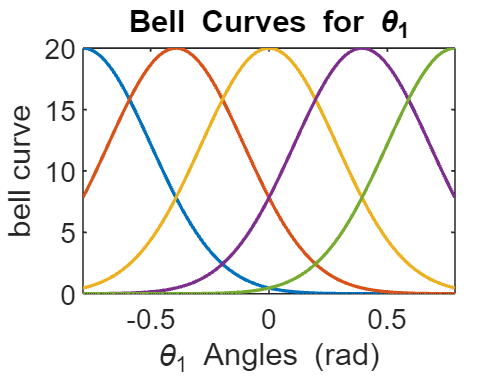

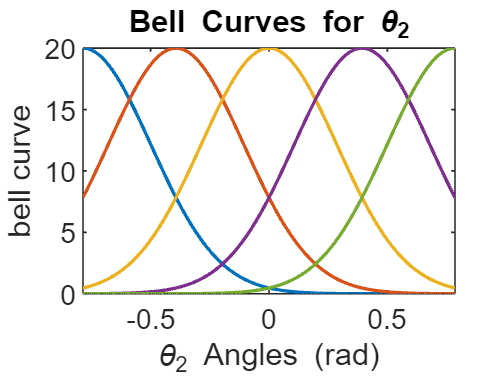

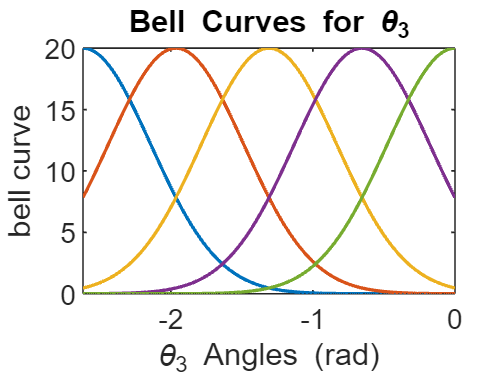

bell_1new =    20.0000   19.9490   19.7970   19.5461   19.2002   18.7644   18.2453   17.6502   16.9876   16.2667   15.4972   14.6889   13.8519   12.9962   12.1312   11.2662   10.4097    9.5693    8.7520    7.9638    7.2097    6.4938    5.8192    5.1882    4.6020    4.0613    3.5659    3.1150    2.7073    2.3409    2.0138    1.7237    1.4678    1.2435    1.0482    0.8790    0.7334    0.6088    0.5028    0.4131    0.3377    0.2747    0.2223    0.1790    0.1433    0.1142    0.0906    0.0714    0.0561    0.0438
    4.1922    4.7443    5.3418    5.9838    6.6690    7.3948    8.1579    8.9538    9.7775   10.6226   11.4820   12.3478   13.2113   14.0633   14.8940   15.6936   16.4519   17.1591   17.8056   18.3825   18.8815   19.2953   19.6179   19.8444   19.9713   19.9968   19.9204   19.7434   19.4683   19.0994   18.6422   18.1033   17.4905   16.8125   16.0785   15.2983   14.4819   13.6393   12.7804   11.9146   11.0510   10.1978    9.3626    8.5520    7.7719    7.0270    6.3212    5.6573    5.0

bell1funcnew = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2new =    20.0000   19.9490   19.7970   19.5461   19.2002   18.7644   18.2453   17.6502   16.9876   16.2667   15.4972   14.6889   13.8519   12.9962   12.1312   11.2662   10.4097    9.5693    8.7520    7.9638    7.2097    6.4938    5.8192    5.1882    4.6020    4.0613    3.5659    3.1150    2.7073    2.3409    2.0138    1.7237    1.4678    1.2435    1.0482    0.8790    0.7334    0.6088    0.5028    0.4131    0.3377    0.2747    0.2223    0.1790    0.1433    0.1142    0.0906    0.0714    0.0561    0.0438
    4.1922    4.7443    5.3418    5.9838    6.6690    7.3948    8.1579    8.9538    9.7775   10.6226   11.4820   12.3478   13.2113   14.0633   14.8940   15.6936   16.4519   17.1591   17.8056   18.3825   18.8815   19.2953   19.6179   19.8444   19.9713   19.9968   19.9204   19.7434   19.4683   19.0994   18.6422   18.1033   17.4905   16.8125   16.0785   15.2983   14.4819   13.6393   12.7804   11.9146   11.0510   10.1978    9.3626    8.5520    7.7719    7.0270    6.3212    5.6573    5.0

bell2funcnew = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3new =    20.0000   19.9490   19.7970   19.5461   19.2002   18.7644   18.2453   17.6502   16.9876   16.2667   15.4972   14.6889   13.8519   12.9962   12.1312   11.2662   10.4097    9.5693    8.7520    7.9638    7.2097    6.4938    5.8192    5.1882    4.6020    4.0613    3.5659    3.1150    2.7073    2.3409    2.0138    1.7237    1.4678    1.2435    1.0482    0.8790    0.7334    0.6088    0.5028    0.4131    0.3377    0.2747    0.2223    0.1790    0.1433    0.1142    0.0906    0.0714    0.0561    0.0438
    4.1922    4.7443    5.3418    5.9838    6.6690    7.3948    8.1579    8.9538    9.7775   10.6226   11.4820   12.3478   13.2113   14.0633   14.8940   15.6936   16.4519   17.1591   17.8056   18.3825   18.8815   19.2953   19.6179   19.8444   19.9713   19.9968   19.9204   19.7434   19.4683   19.0994   18.6422   18.1033   17.4905   16.8125   16.0785   15.2983   14.4819   13.6393   12.7804   11.9146   11.0510   10.1978    9.3626    8.5520    7.7719    7.0270    6.3212    5.6573    5.0

bell3funcnew = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


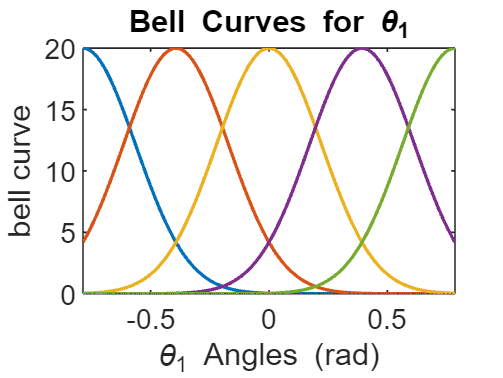

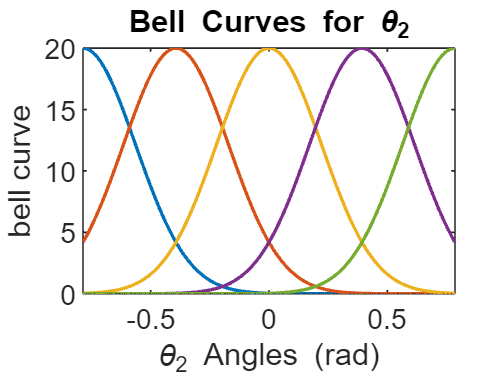

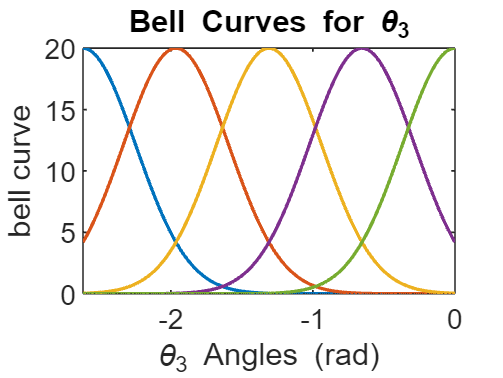

bell_1new = 5×100
   20.0000   19.9287   19.7163   19.3674   18.8893   18.2919   17.5872   16.7894   15.9138   14.9764   13.9940   12.9829   11.9592   10.9378    9.9324    8.9553    8.0168    7.1256    6.2884    5.5101    4.7937    4.1408    3.5514    3.0242    2.5569    2.1465    1.7891    1.4806    1.2165    0.9925
    2.2439    2.6683    3.1503    3.6928    4.2981    4.9669    5.6989    6.4923    7.3436    8.2473    9.1963   10.1816   11.1921   12.2155   13.2375   14.2429   15.2156   16.1391   16.9968   17.7727   18.4518   19.0204   19.4671   19.7825   19.9599   19.9955   19.8887   19.6417   19.2597   18.7507
    0.0032    0.0045    0.0063    0.0089    0.0123    0.0170    0.0232    0.0316    0.0427    0.0572    0.0761    0.1005    0.1319    0.1717    0.2221    0.2852    0.3635    0.4601    0.5783    0.7216    0.8941    1.0998    1.3433    1.6290    1.9614    2.3448    2.7832    3.2801    3.8382    4.4593
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell1funcnew = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2new = 5×100
   20.0000   19.9287   19.7163   19.3674   18.8893   18.2919   17.5872   16.7894   15.9138   14.9764   13.9940   12.9829   11.9592   10.9378    9.9324    8.9553    8.0168    7.1256    6.2884    5.5101    4.7937    4.1408    3.5514    3.0242    2.5569    2.1465    1.7891    1.4806    1.2165    0.9925
    2.2439    2.6683    3.1503    3.6928    4.2981    4.9669    5.6989    6.4923    7.3436    8.2473    9.1963   10.1816   11.1921   12.2155   13.2375   14.2429   15.2156   16.1391   16.9968   17.7727   18.4518   19.0204   19.4671   19.7825   19.9599   19.9955   19.8887   19.6417   19.2597   18.7507
    0.0032    0.0045    0.0063    0.0089    0.0123    0.0170    0.0232    0.0316    0.0427    0.0572    0.0761    0.1005    0.1319    0.1717    0.2221    0.2852    0.3635    0.4601    0.5783    0.7216    0.8941    1.0998    1.3433    1.6290    1.9614    2.3448    2.7832    3.2801    3.8382    4.4593
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell2funcnew = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3new = 5×100
   20.0000   19.9287   19.7163   19.3674   18.8893   18.2919   17.5872   16.7894   15.9138   14.9764   13.9940   12.9829   11.9592   10.9378    9.9324    8.9553    8.0168    7.1256    6.2884    5.5101    4.7937    4.1408    3.5514    3.0242    2.5569    2.1465    1.7891    1.4806    1.2165    0.9925
    2.2439    2.6683    3.1503    3.6928    4.2981    4.9669    5.6989    6.4923    7.3436    8.2473    9.1963   10.1816   11.1921   12.2155   13.2375   14.2429   15.2156   16.1391   16.9968   17.7727   18.4518   19.0204   19.4671   19.7825   19.9599   19.9955   19.8887   19.6417   19.2597   18.7507
    0.0032    0.0045    0.0063    0.0089    0.0123    0.0170    0.0232    0.0316    0.0427    0.0572    0.0761    0.1005    0.1319    0.1717    0.2221    0.2852    0.3635    0.4601    0.5783    0.7216    0.8941    1.0998    1.3433    1.6290    1.9614    2.3448    2.7832    3.2801    3.8382    4.4593
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell3funcnew = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


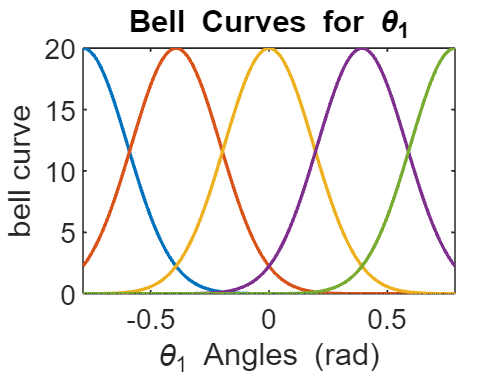

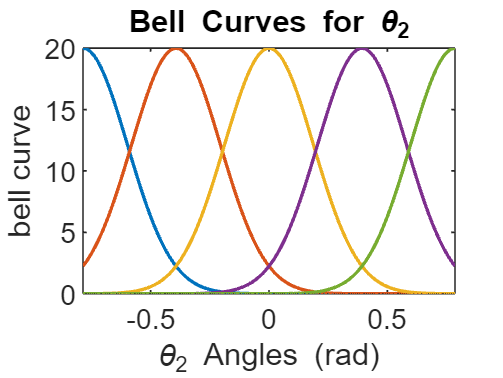

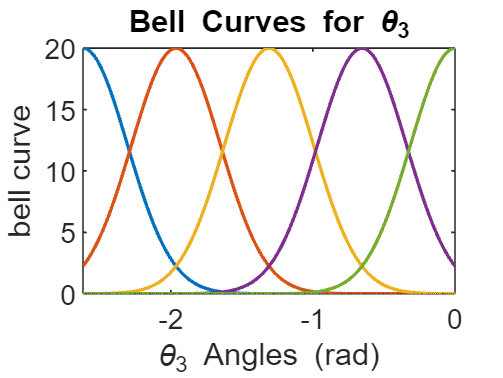

bell_1new = 5×100
   20.0000   19.9084   19.6360   19.1904   18.5834   17.8312   16.9530   15.9707   14.9078   13.7885   12.6366   11.4751   10.3251    9.2054    8.1321    7.1183    6.1740    5.3059    4.5183    3.8124    3.1873    2.6404    2.1674    1.7628    1.4206    1.1344    0.8976    0.7037    0.5467    0.4208
    1.2011    1.5007    1.8578    2.2790    2.7700    3.3361    3.9812    4.7075    5.5155    6.4031    7.3656    8.3953    9.4816   10.6104   11.7652   12.9263   14.0723   15.1798   16.2248   17.1832   18.0318   18.7495   19.3175   19.7207   19.9484   19.9943   19.8570   19.5405   19.0532   18.4083
    0.0003    0.0004    0.0006    0.0010    0.0015    0.0023    0.0034    0.0050    0.0074    0.0107    0.0155    0.0222    0.0314    0.0441    0.0614    0.0847    0.1157    0.1566    0.2101    0.2793    0.3679    0.4802    0.6210    0.7957    1.0102    1.2709    1.5843    1.9569    2.3950    2.9044
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell1funcnew = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2new = 5×100
   20.0000   19.9084   19.6360   19.1904   18.5834   17.8312   16.9530   15.9707   14.9078   13.7885   12.6366   11.4751   10.3251    9.2054    8.1321    7.1183    6.1740    5.3059    4.5183    3.8124    3.1873    2.6404    2.1674    1.7628    1.4206    1.1344    0.8976    0.7037    0.5467    0.4208
    1.2011    1.5007    1.8578    2.2790    2.7700    3.3361    3.9812    4.7075    5.5155    6.4031    7.3656    8.3953    9.4816   10.6104   11.7652   12.9263   14.0723   15.1798   16.2248   17.1832   18.0318   18.7495   19.3175   19.7207   19.9484   19.9943   19.8570   19.5405   19.0532   18.4083
    0.0003    0.0004    0.0006    0.0010    0.0015    0.0023    0.0034    0.0050    0.0074    0.0107    0.0155    0.0222    0.0314    0.0441    0.0614    0.0847    0.1157    0.1566    0.2101    0.2793    0.3679    0.4802    0.6210    0.7957    1.0102    1.2709    1.5843    1.9569    2.3950    2.9044
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell2funcnew = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3new = 5×100
   20.0000   19.9084   19.6360   19.1904   18.5834   17.8312   16.9530   15.9707   14.9078   13.7885   12.6366   11.4751   10.3251    9.2054    8.1321    7.1183    6.1740    5.3059    4.5183    3.8124    3.1873    2.6404    2.1674    1.7628    1.4206    1.1344    0.8976    0.7037    0.5467    0.4208
    1.2011    1.5007    1.8578    2.2790    2.7700    3.3361    3.9812    4.7075    5.5155    6.4031    7.3656    8.3953    9.4816   10.6104   11.7652   12.9263   14.0723   15.1798   16.2248   17.1832   18.0318   18.7495   19.3175   19.7207   19.9484   19.9943   19.8570   19.5405   19.0532   18.4083
    0.0003    0.0004    0.0006    0.0010    0.0015    0.0023    0.0034    0.0050    0.0074    0.0107    0.0155    0.0222    0.0314    0.0441    0.0614    0.0847    0.1157    0.1566    0.2101    0.2793    0.3679    0.4802    0.6210    0.7957    1.0102    1.2709    1.5843    1.9569    2.3950    2.9044
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell3funcnew = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


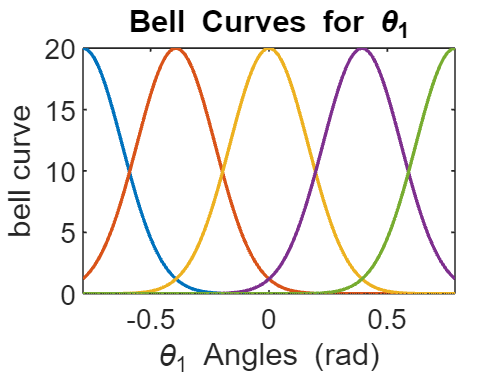

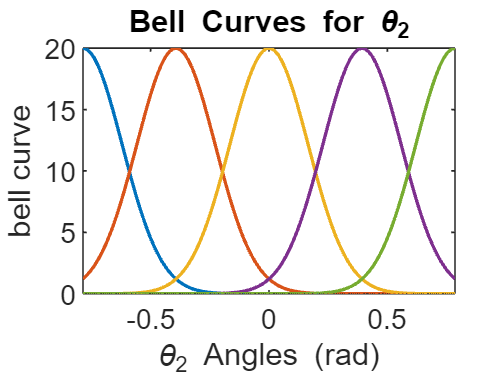

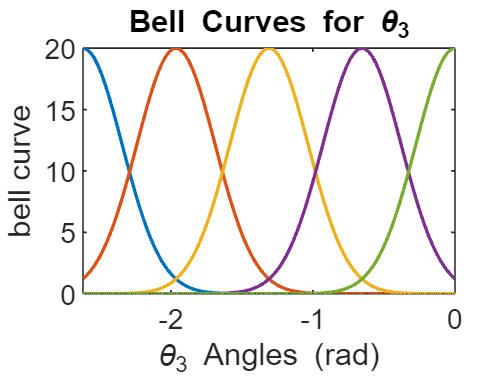

bell_1new = 5×100
   20.0000   19.8881   19.5561   19.0150   18.2825   17.3821   16.3416   15.1919   13.9654   12.6947   11.4109   10.1424    8.9143    7.7474    6.6582    5.6582    4.7548    3.9510    3.2464    2.6377    2.1193    1.6837    1.3227    1.0275    0.7893    0.5996    0.4503    0.3345    0.2457    0.1784
    0.6429    0.8440    1.0956    1.4064    1.7852    2.2408    2.7812    3.4134    4.1425    4.9713    5.8994    6.9225    8.0324    9.2163   10.4566   11.7314   13.0148   14.2774   15.4878   16.6132   17.6215   18.4824   19.1690   19.6592   19.9370   19.9930   19.8254   19.4398   18.8490   18.0721
    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0008    0.0013    0.0020    0.0032    0.0049    0.0075    0.0113    0.0170    0.0251    0.0368    0.0533    0.0763    0.1081    0.1514    0.2096    0.2871    0.3887    0.5203    0.6889    0.9018    1.1675    1.4944    1.8916
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell1funcnew = function_handle with value:
    @(x)exp(-c/range(theta1)^2*(x-theta1').^2)


bell_2new = 5×100
   20.0000   19.8881   19.5561   19.0150   18.2825   17.3821   16.3416   15.1919   13.9654   12.6947   11.4109   10.1424    8.9143    7.7474    6.6582    5.6582    4.7548    3.9510    3.2464    2.6377    2.1193    1.6837    1.3227    1.0275    0.7893    0.5996    0.4503    0.3345    0.2457    0.1784
    0.6429    0.8440    1.0956    1.4064    1.7852    2.2408    2.7812    3.4134    4.1425    4.9713    5.8994    6.9225    8.0324    9.2163   10.4566   11.7314   13.0148   14.2774   15.4878   16.6132   17.6215   18.4824   19.1690   19.6592   19.9370   19.9930   19.8254   19.4398   18.8490   18.0721
    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0008    0.0013    0.0020    0.0032    0.0049    0.0075    0.0113    0.0170    0.0251    0.0368    0.0533    0.0763    0.1081    0.1514    0.2096    0.2871    0.3887    0.5203    0.6889    0.9018    1.1675    1.4944    1.8916
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell2funcnew = function_handle with value:
    @(x)exp(-c/range(theta2)^2*(x-theta2').^2)


bell_3new = 5×100
   20.0000   19.8881   19.5561   19.0150   18.2825   17.3821   16.3416   15.1919   13.9654   12.6947   11.4109   10.1424    8.9143    7.7474    6.6582    5.6582    4.7548    3.9510    3.2464    2.6377    2.1193    1.6837    1.3227    1.0275    0.7893    0.5996    0.4503    0.3345    0.2457    0.1784
    0.6429    0.8440    1.0956    1.4064    1.7852    2.2408    2.7812    3.4134    4.1425    4.9713    5.8994    6.9225    8.0324    9.2163   10.4566   11.7314   13.0148   14.2774   15.4878   16.6132   17.6215   18.4824   19.1690   19.6592   19.9370   19.9930   19.8254   19.4398   18.8490   18.0721
    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0008    0.0013    0.0020    0.0032    0.0049    0.0075    0.0113    0.0170    0.0251    0.0368    0.0533    0.0763    0.1081    0.1514    0.2096    0.2871    0.3887    0.5203    0.6889    0.9018    1.1675    1.4944    1.8916
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

bell3funcnew = function_handle with value:
    @(x)exp(-c/range(theta3)^2*(x-theta3').^2)


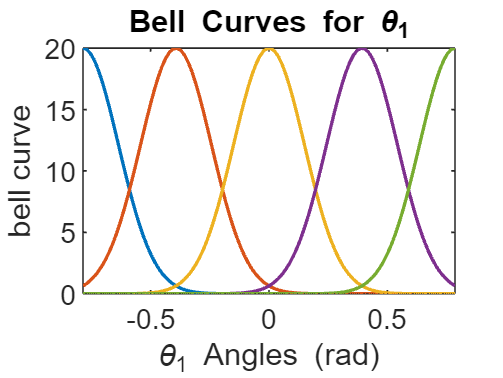

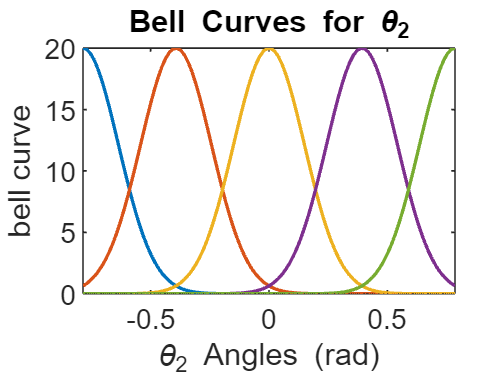

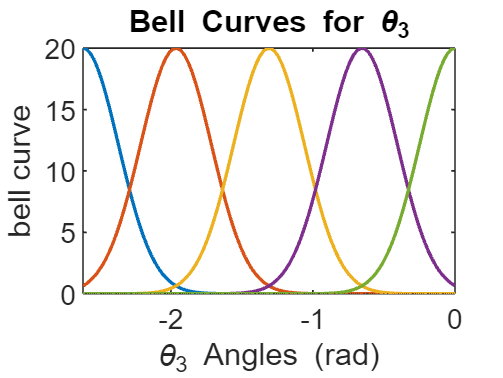

    % global frame = thorax frame
    g_th = [0 0 0];
    
    % identity matrix
    I = [1 0 0;...
        0 1 0;...
        0 0 1]
    % zero configuration 3x1 translatio vector
    g_T_l2 = [0 (l_fe+l_ti) l_th]' % where the foot is when all angles are 0.
    % Transformation from the thorax frame to the end effector in the zero
    % config. 
    g_foot_thorax_zero = [I g_T_l2;...
                     0 0 0 1]

### Step 2. Find the joint twists - zeta

- 
$$v=\textrm{cross}\left(\omega_{i\;} ,q_i \right)$$


- angle value describing position of rotational axis of thorax - coxa of the middle leg: psi = 37 degrees ---> Table 2 of Cruse, H. et al. 

    omega1 = [0 sind(37) cosd(37)]'; % omega 1 = omega for thorax/coxa
    q1 = [0 0 l_th]';
    v1 = cross(-omega1,q1);
    zeta1 = [v1;...
            omega1]
    
    omega2 = [-1 0 0]'; % omega 2 = omega for the coxa-trochanter
    v2 = cross(-omega2,q1);
    zeta2 = [v2;...
            omega2]
    
    omega3 = [-1 0 0]'; % omega 3 = omega for the femur-tibia
    q2 = [0 l_fe l_th]';
    v3 = cross(-omega3,q2);
    zeta3 = [v3;...
            omega3]

### Step 3. Calculate the rotation matrix omegas in cross product matrix notation:

    omega_skew1 = [0 -omega1(3) omega1(2);...
                  omega1(3) 0 -omega1(1);...
                  -omega1(2) omega1(1) 0]
    omega_skew2 = [0 -omega2(3) omega2(2);...
                  omega2(3) 0 -omega2(1);...
                  -omega2(2) omega2(1) 0]
    omega_skew3 = [0 -omega3(3) omega3(2);...
                  omega3(3) 0 -omega3(1);...
                  -omega3(2) omega3(1) 0]
    output = NaN(5,5,5,6) % for tuning

### Rodriques' Rotation Formula:

    m = 1;
    for i = 1:length(theta1)
        for j = 1:length(theta2)
            for k = 1:length(theta3)
                exp_omega_skew1 = I + (omega_skew1).*sin(theta1(i)) + (omega_skew1)^2.*(1-cos(theta1(i)));
                exp_omega_skew2 = I + (omega_skew2).*sin(theta2(j)) + (omega_skew2)^2.*(1-cos(theta2(j)));
                exp_omega_skew3 = I + (omega_skew3).*sin(theta3(k)) + (omega_skew3)^2.*(1-cos(theta3(k)));
                

### Step 4. Calculate the translation.

                % calculate translation
                t1 = (I-exp_omega_skew1)*(cross(omega1,v1)) + omega1*(omega1)'*(v1)*(theta1(i));
                t2 = (I-exp_omega_skew2)*(cross(omega2,v2)) + omega2*(omega2)'*(v2)*(theta2(j));
                t3 = (I-exp_omega_skew3)*(cross(omega3,v3)) + omega3*(omega3)'*(v3)*(theta3(k));
                

### Step 5. Calculate the matrix exponential.

                % calculate the matrix exponential
                exp_Twist_skew1 = [exp_omega_skew1 t1;...
                                   0 0 0 1];
                exp_Twist_skew2 = [exp_omega_skew2 t2;...
                                   0 0 0 1];
                exp_Twist_skew3 = [exp_omega_skew3 t3;...
                                   0 0 0 1];
                

### Step 6. Compose the structure equation.

                % compose the structure equation
                g_foot_thorax = exp_Twist_skew1*exp_Twist_skew2*exp_Twist_skew3*g_foot_thorax_zero;
                output(i,j,k,1)=(theta1(i));
                output(i,j,k,2)=(theta2(j));
                output(i,j,k,3)=(theta3(k));
                output(i,j,k,4)=g_foot_thorax(1,4);
                output(i,j,k,5)=g_foot_thorax(2,4);
                output(i,j,k,6)=g_foot_thorax(3,4);
                fprintf('%i\n',100*m/n^3)
                m=m+1;
            end
        end 
    end 

## 3.3 Tuning Parameters within the Model

$P_x$ Output is the output(:,4)

$P_y$ Output is the output(:,5)

$P_z$ Output is the output(:,6)

### Figure: Scatterplot 

    % we want Py for now
    figure
    scatter3(reshape(output(:,:,:,1),[],1),reshape(output(:,:,:,2),[],1),reshape(output(:,:,:,3),[],1),[],reshape(output(:,:,:,5),[],1),'filled')
    title('P_y')
    xlabel('\theta_1')
    ylabel('\theta_2')
    zlabel('\theta_3')
    colorbar

Time vector:

    tmax = 5; % [s]
    dt = 0.01; % [s]
    t = 0:dt:tmax; % [s]
    numSteps = length(t);
    
    minPy = min(output(:,:,:,5),[],'all');
    maxPy = max(output(:,:,:,5),[],'all');
    kvar = (output(:,:,:,5) - minPy)/(maxPy - minPy);

### Sinusoids

Sinusoid Periods:

    T1 = 1;
    T2 = 0.85;
    T3 = 0.7;
    
    % List of theta values as a function of time for each angle:
    
    th1list = 1*(range(theta1)*sin(2*pi*t/T1)/2 + mean(theta1));
    th2list = 1*(range(theta2)*sin(2*pi*t/T2)/2 + mean(theta2));
    th3list = 1*(range(theta3)*sin(2*pi*t/T3)/2 + mean(theta3));
    
    numNeurons=n^3;
    
    Ui = NaN(numSteps,numNeurons);
    Usoma = NaN(n,n,n);
    Py = NaN(numSteps,1);

## Width

    c = 300; % width

Changing the width value, or c, will change the sigmoid function (erf) to be steeper or flatter, i.e.,

- To flatten the sigmoid, c = 1.

- To steepen the sigmoid, c = 15. 

    theta1test = linspace(min(theta1),max(theta1),100);
    theta2test = linspace(min(theta2),max(theta2),100);
    theta3test = linspace(min(theta3),max(theta3),100);

Create the bell functions:

    %bell_1 = R*exp(-c*(theta1test-b).^2)
    bell_1 = R*exp(-c/range(theta1)^2*(theta1test-theta1').^2)
    bell1func = @(x) exp(-c/range(theta1)^2*(x-theta1').^2)
    
    bell_2 = R*exp(-c/range(theta2)^2*(theta2test-theta2').^2)
    bell2func = @(x) exp(-c/range(theta2)^2*(x-theta2').^2)
    
    bell_3 = R*exp(-c/range(theta3)^2*(theta3test-theta3').^2)
    bell3func = @(x) exp(-c/range(theta3)^2*(x-theta3').^2)

    figure 
    grid on
    plot(theta1test,bell_1,'linewidth',1)
    xlabel('\theta_1 Angles (rad)')
    ylabel('bell curve')
    title('Bell Curves for \theta_1')
    xlim([min(theta1),max(theta1)])
    
    figure 
    grid on
    plot(theta2test,bell_2,'linewidth',1)
    xlabel('\theta_2 Angles (rad)')
    ylabel('bell curve')
    title('Bell Curves for \theta_2')
    xlim([min(theta2),max(theta2)])
    
    figure 
    grid on
    plot(theta3test,bell_3,'linewidth',1)
    xlabel('\theta_3 Angles (rad)')
    ylabel('bell curve')
    title('Bell Curves for \theta_3')
    xlim([min(theta3),max(theta3)])
    
    %Plot the theta lists, or the theta angles through time:
    figure
    grid on
    plot(t,th1list,'linewidth',1)
    hold on
    plot(t,th2list,'linewidth',1)
    plot(t,th3list,'linewidth',1)
    xlabel('Time (s)')
    ylabel('Angle (rad)')
    legend('\theta_1','\theta_2','\theta_3','location','south')
    title('\theta Angles through Time')


# Results

Scratch Work Code from 2-6-2023: 

What order to calculate l's?

- Lowest to highest total activity.

- Break symmetry in network.

- Theta_hip_max doesn't equal Theta_knee_ma x, etc.

Calculate all U's.

Formulate the function to change G's until Upy is correct.

Only want to calculate G's that are currently unknown.

Follow "elimination" process. 

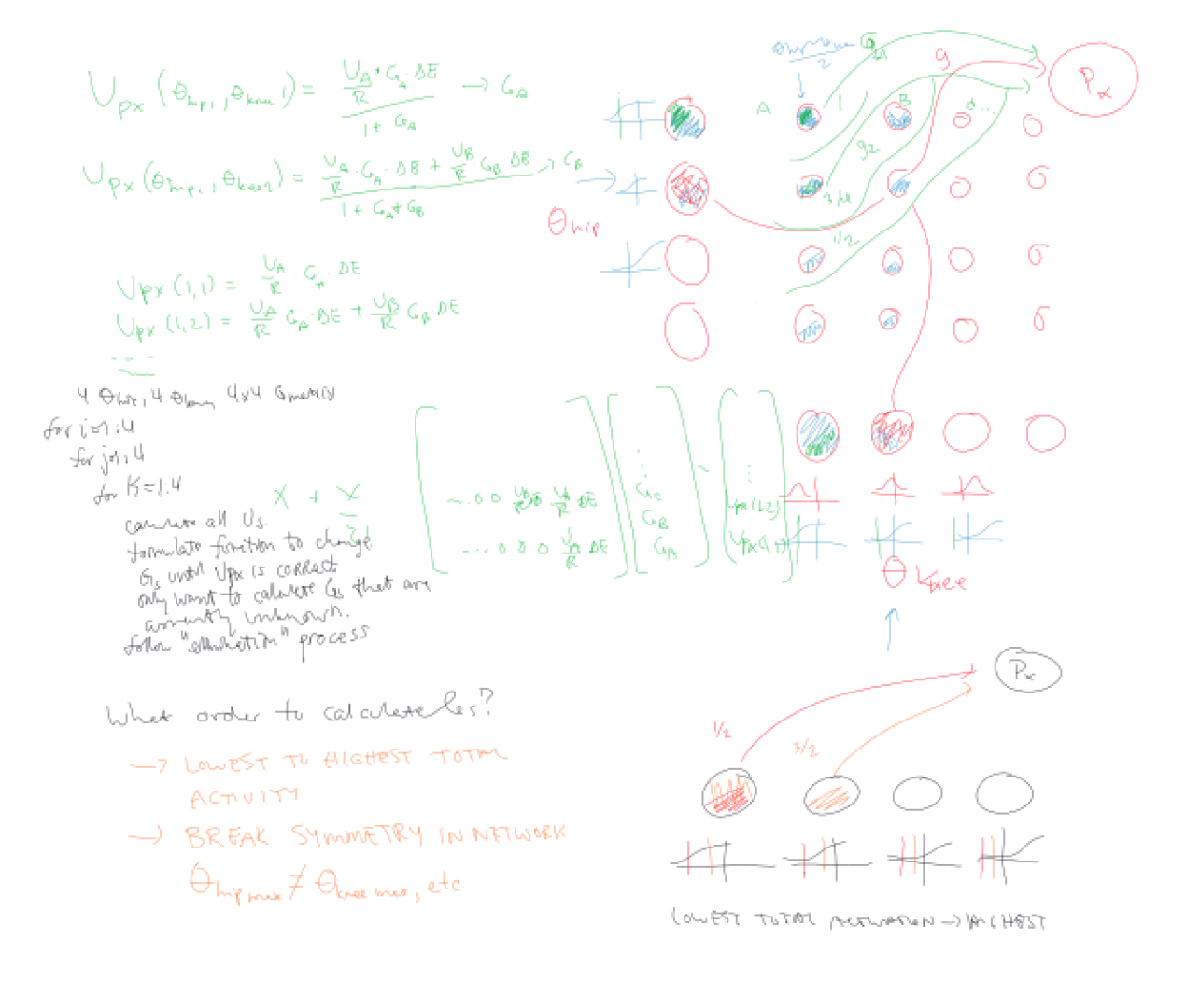


$$k=\frac{\left(P_y -\min \left(P_y \right)\right)}{\left(\max \left(P_y \right)-\min \left(P_y \right)\right)}$$



$$U_{P_y } \left(\theta_{x_1 } ,\theta_{y_1 } ,\theta_{z_1 } \right)=\frac{\left(\frac{U_A }{R}*G_A *\Delta E\;\right)}{\left(1+G_A \right)}$$


$\Delta E=60\;\textrm{mV}$ which is the reversal potential of the chemical synapse. 


$$G_{y_i } =G_A$$


Tuning:

- Make 5x5x5 grid of angles and calculate every Usoma value. Then use this to calculate all Gyi’s.

    Usomadesired = kvar*R;

Testing:

- When testing: use varying-angles-over-time data (the theta lists or thetatests?), by running those angles through the network and seeing what Usomas you get out.

## Binary Code - Least Squares Problem

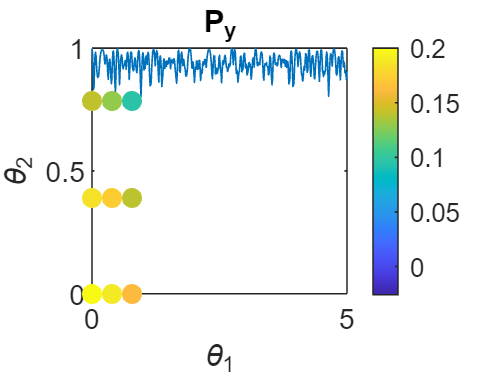

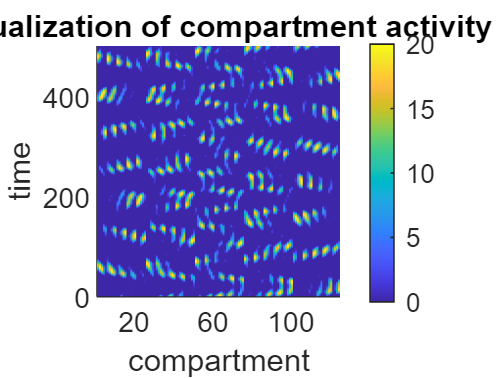

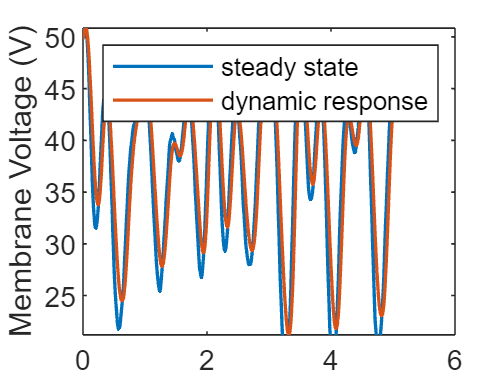

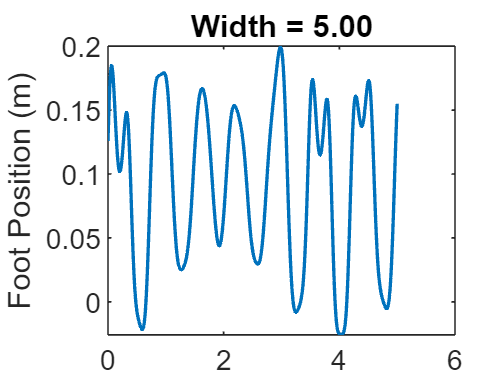

h =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


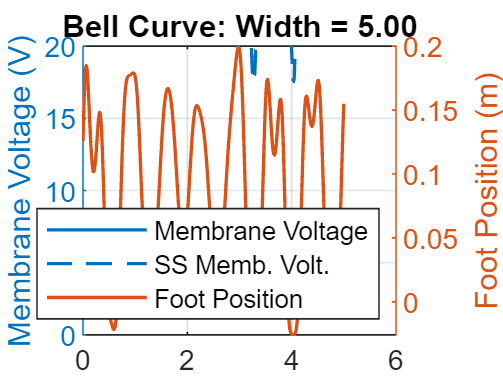

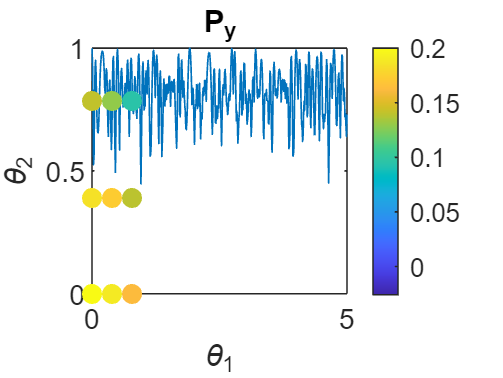

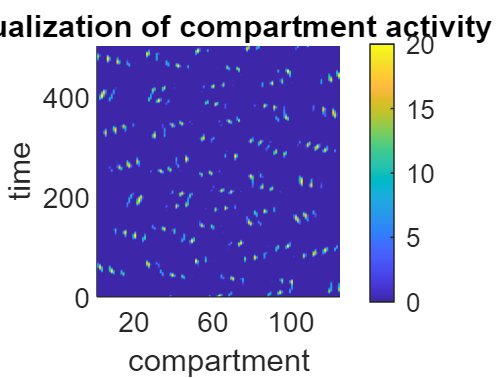

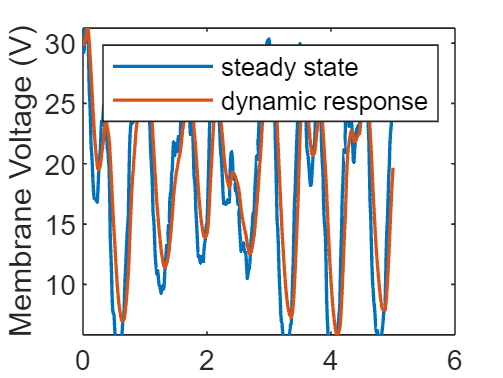

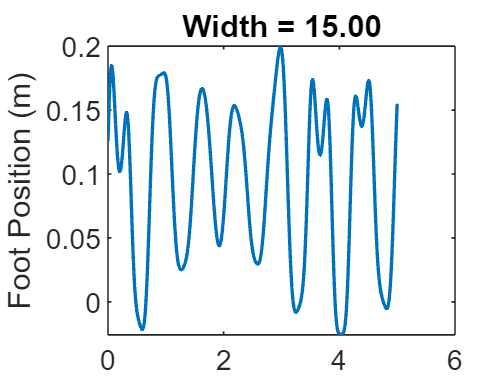

h =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


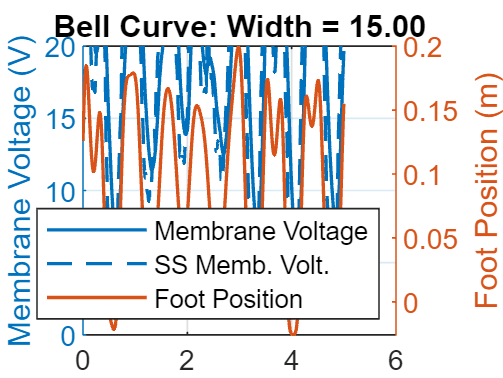

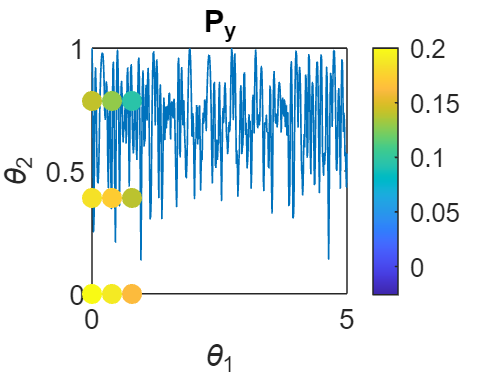

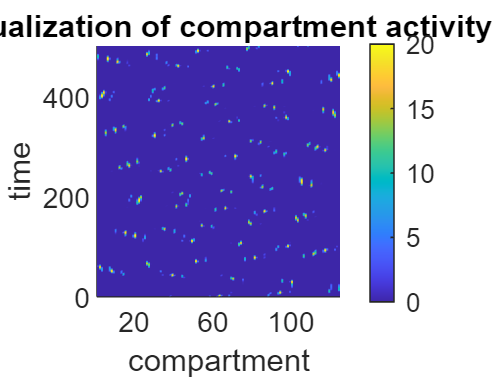

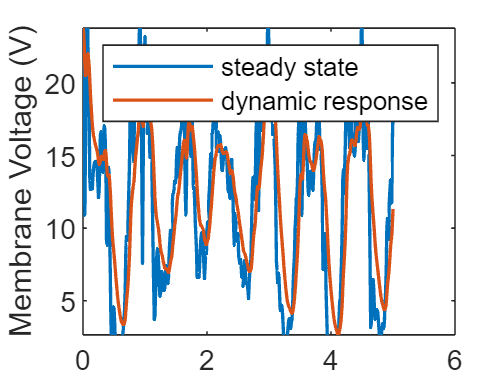

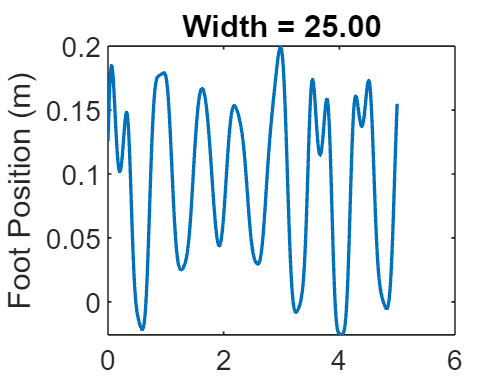

h =   Figure (39) with properties:

      Number: 39
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


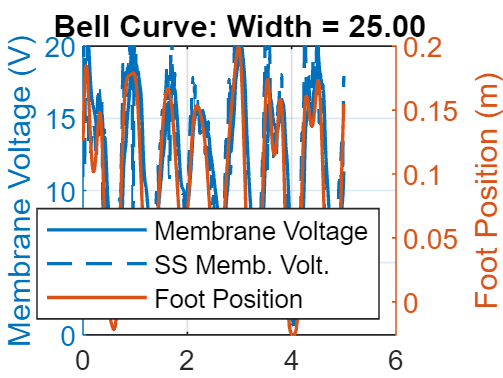

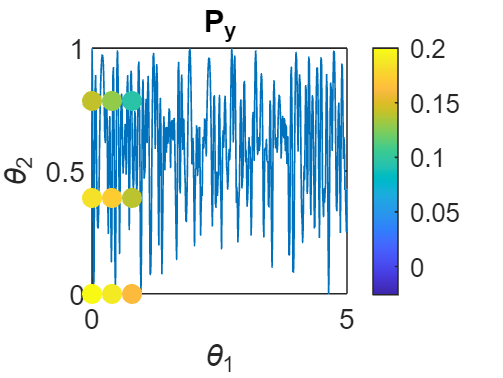

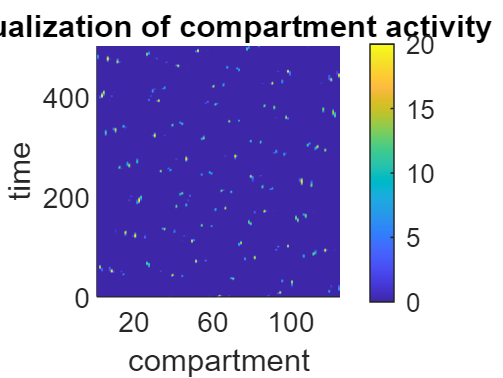

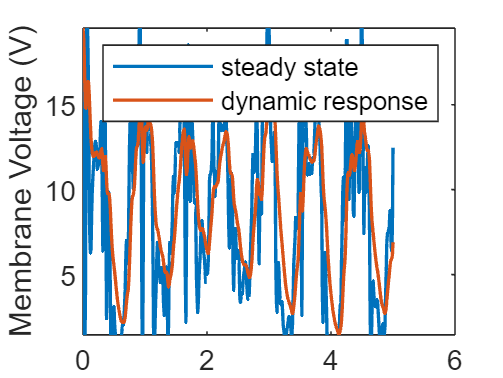

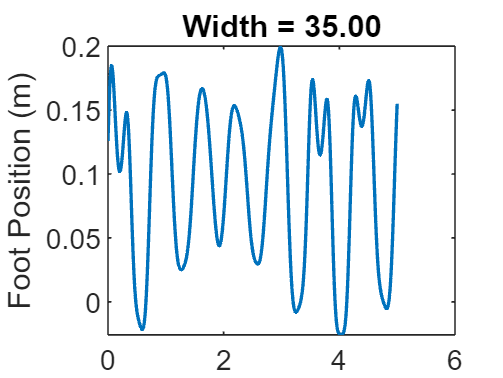

h =   Figure (52) with properties:

      Number: 52
        Name: ''
       Color: [1 1 1]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


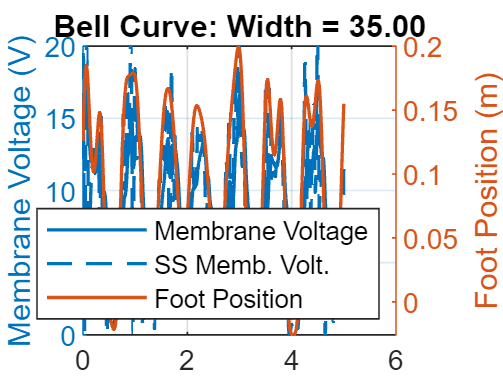

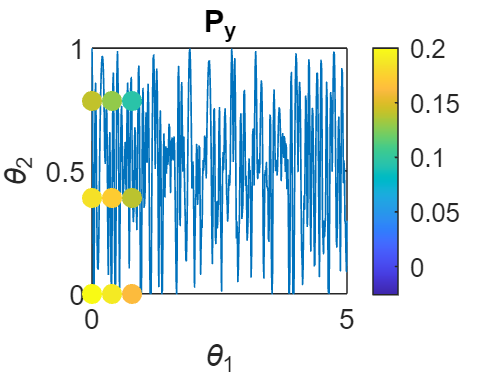

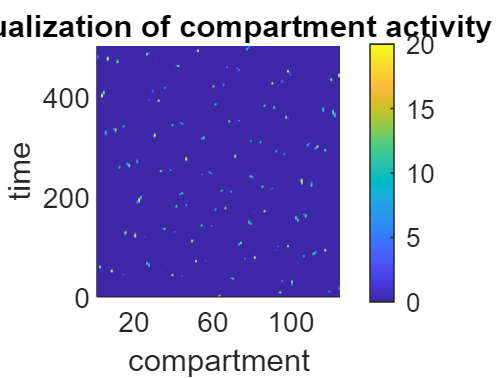

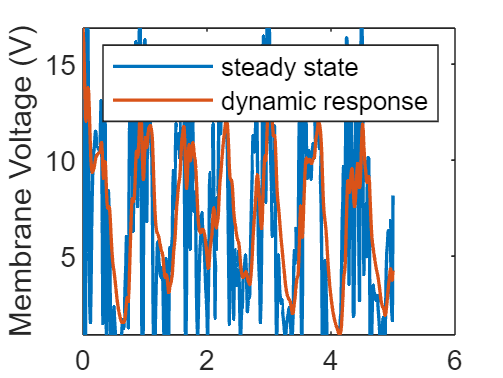

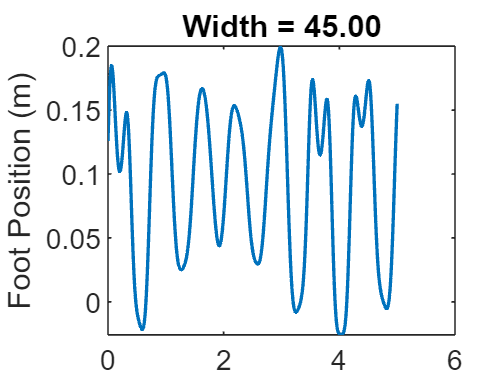

h =   Figure (65) with properties:

      Number: 65
        Name: ''
       Color: [1 1 1]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


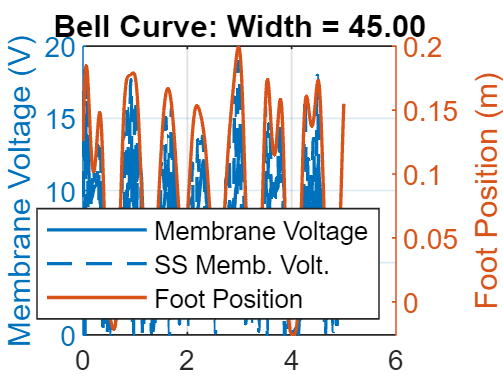

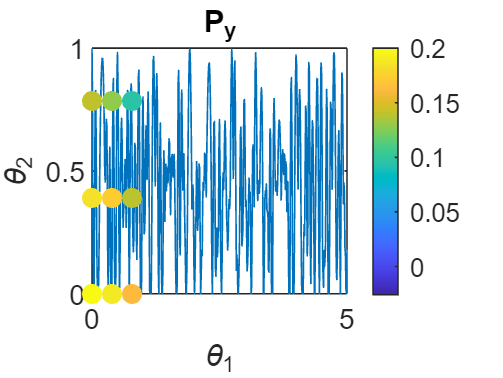

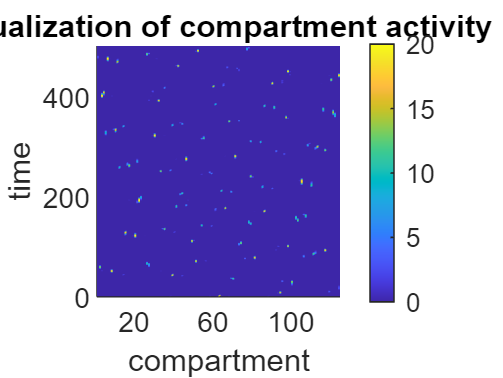

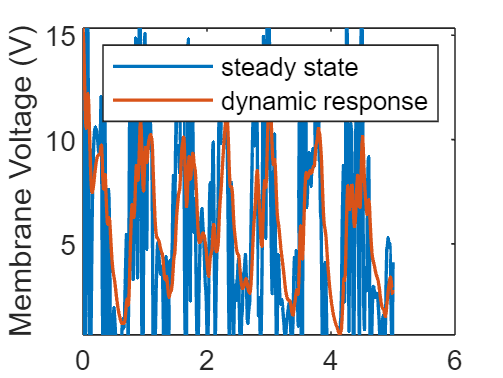

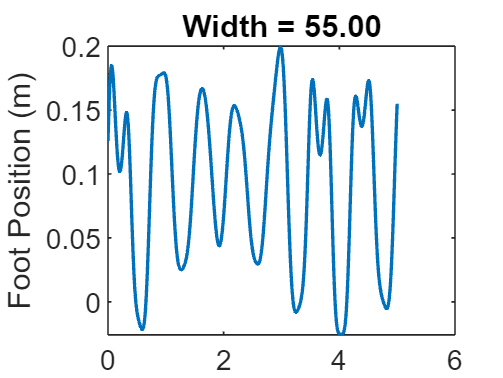

h =   Figure (78) with properties:

      Number: 78
        Name: ''
       Color: [1 1 1]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


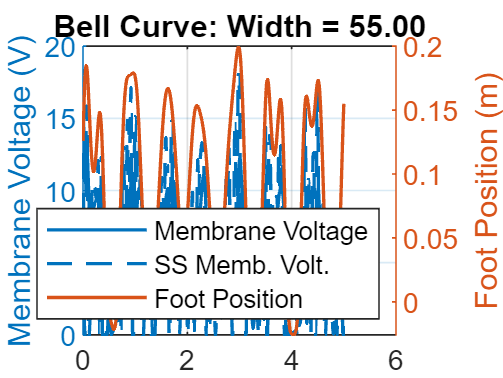

    b = Usomadesired(:);
    Evec = Eex + zeros(size(kvar(:)));
    Evec(kvar<0) = Ein;
    Gmax = (kvar(:)*R)./(Evec - (kvar(:)*R));
    Gmax_bell_OG = Gmax;
    
    %To "blur" or "smooth out" the Gmax values, we will need to keep them in an

    %N-D grid (i.e., a cube when N=3). We will convolve this with a "kernel"
    %that represents how much our bellcurves overlap.
    GmaxCube = (kvar*R)./(Eex - kvar*R);
    if any(GmaxCube < 0)
        error('Synaptic conductance values must be greater than or equal to 0.')
    end


### Convolution:

    c = width(n); % width that we actually want for our sensory system/decoder network.
    
    bell_1new = R*exp(-c/range(theta1)^2*(theta1test-theta1').^2)
    bell1funcnew = @(x) exp(-c/range(theta1)^2*(x-theta1').^2)
    
    bell_2new = R*exp(-c/range(theta2)^2*(theta2test-theta2').^2)
    bell2funcnew = @(x) exp(-c/range(theta2)^2*(x-theta2').^2)
    
    bell_3new = R*exp(-c/range(theta3)^2*(theta3test-theta3').^2)
    bell3funcnew = @(x) exp(-c/range(theta3)^2*(x-theta3').^2)
    
    figure 
    grid on
    plot(theta1test,bell_1new,'linewidth',1)
    xlabel('\theta_1 Angles (rad)')
    ylabel('bell curve')
    title('Bell Curves for \theta_1')
    xlim([min(theta1),max(theta1)])
    
    figure 
    grid on
    plot(theta2test,bell_2new,'linewidth',1)
    xlabel('\theta_2 Angles (rad)')
    ylabel('bell curve')
    title('Bell Curves for \theta_2')
    xlim([min(theta2),max(theta2)])
    
    figure 
    grid on
    plot(theta3test,bell_3new,'linewidth',1)
    xlabel('\theta_3 Angles (rad)')
    ylabel('bell curve')
    title('Bell Curves for \theta_3')
    xlim([min(theta3),max(theta3)])
    
    
    %We are going to smooth out the GmaxCube grid using a Gaussian "kernel". A
    %kernel is just an N-D grid of the same dimensions, where the value at each
    %position in the kernal tells us how much of the corresponding value in the
    %GmaxCube to add there. It's basically a weighted sum. If you were to make
    %c above = 300, then only 1 sensory cell would be active at a time, and the
    %resulting kernel would be a 3D cube of all 0s except for a 1 in the very
    %center. This means that the value that is already there makes up 100% of
    %the weight, because none of the other sensory cells are active, anyway. 
    %To make the kernel in a general case, we'll use bellfuncnew to find how
    %active each sensory cell is at a given angle, reshape each one like we do
    %when calculating sens1bellBlock, sens2bellBlock, etc., then .* them
    %together.
    amplitudes1 = repmat(reshape(bell1funcnew(mean(theta1)),[5,1,1]),[1,5,5]);
    amplitudes2 = repmat(reshape(bell2funcnew(mean(theta2)),[1,5,1]),[5,1,5]);
    amplitudes3 = repmat(reshape(bell3funcnew(mean(theta3)),[1,1,5]),[5,5,1]);
    kernel = amplitudes1.*amplitudes2.*amplitudes3;
    
    %The only adjustment we have to make to the kernel is to normalize it so
    %that its sum along all directions is 1. For best results, the kernel
    %should get to 0 before the limits of each theta. That is, in the "Bell
    %Curves for \theta_1" plot, the yellow bell curve should get close to 0 at
    %the edges. NSS.
    kernel = kernel/sum(kernel,"all");
    
    %Convolve GmaxCube with the kernel. Then save it in the shape we need for
    %subsequent calculations, as a column vector. NSS.
    Gmax_bell_new = convn(GmaxCube, kernel, 'same');
    Gmax_bell_new = Gmax_bell_new(:);
    
    %This approach with wide bell curves and the convolution is an alternative
    %to the erfs and nerfs, so I commented those out everywhere. It also means
    %we no longer need the "back propagation" step, so I commented that out,
    %too. If this approach works, I think it is quite neat, because we can
    %calculate all the network values ahead of time. NSS.

## Combos

%     hSensoryScatter = figure;
%     set(hSensoryScatter, 'Visible', 'on');
%     v = VideoWriter('Sensory Field');
%     v.FrameRate = numSteps/tmax;
%     open(v);
    
    Usomanew = NaN(size(th1list));
    Ucomp_bell = NaN(5*5*5,numSteps);
    Ucomp_erf = NaN(5*5*5,numSteps);
    Ucomp_nerf = NaN(5*5*5,numSteps);
    Ucomp_all = NaN(5*5*5,numSteps);
    C = .1; %uF
    %Usoma = NaN(size(th1list));
    for i = 1:numSteps

Bell Curves

        sensor1bell = bell1funcnew(th1list(i));
        sensor2bell = bell2funcnew(th2list(i));
        sensor3bell = bell3funcnew(th3list(i));

Use Ucomp to insert whichever you want out.   

## Usoma

    %   %Calculate contribution of each sensor to each compartment     
        sens1block = repmat(reshape(sensor1bell,[5,1,1]),[1,5,5]);
        sens2block = repmat(reshape(sensor2bell,[1,5,1]),[5,1,5]);
        sens3block = repmat(reshape(sensor3bell,[1,1,5]),[5,5,1]);
    
    % bell
        bperm = max(0, sens1block + sens2block + sens3block - 2);
        bellCurveMax(i) = max(bperm,[],'all');
        Ucomp_bell(:,i) = R*bperm(:);
    %     Gsyn_bell(:,i) = min(max(Ucomp_bell(:,i)/R,0),1).*Gmax_bell_OG;
        Gsyn_bell(:,i) = min(max(Ucomp_bell(:,i)/R,0),1).*Gmax_bell_new;
        Gbell(i) = 1 + sum(Gsyn_bell(:,i));

#### New Usoma for Bell Curve:

        %A couple of these lines didn't use "Gsyn_bell" and "Gbell", so I
        %updated this to make sure it did. NSS.
        Usomanew_SSbell(i) = sum(Evec.*Gsyn_bell(:,i))./Gbell(i);
        if i == 1
            Usomanew_bell(i) = Usomanew_SSbell(i);
        else
            delbU(i) = dt/C*(-Usomanew_bell(i-1) + sum(Gsyn_bell(:,i).*(Evec - Usomanew_bell(i-1)),'all'));
            Usomanew_bell(i) = Usomanew_bell(i-1) + delbU(i);
        end

#### Calculate foot position:

        %Calculate foot position
        exp_omega_skew1 = I + (omega_skew1).*sin(th1list(i)) + (omega_skew1)^2.*(1-cos(th1list(i)));
        exp_omega_skew2 = I + (omega_skew2).*sin(th2list(i)) + (omega_skew2)^2.*(1-cos(th2list(i)));
        exp_omega_skew3 = I + (omega_skew3).*sin(th3list(i)) + (omega_skew3)^2.*(1-cos(th3list(i)));
        % calculate translation
        t1 = (I-exp_omega_skew1)*(cross(omega1,v1)) + omega1*(omega1)'*(v1)*(th1list(i));
        t2 = (I-exp_omega_skew2)*(cross(omega2,v2)) + omega2*(omega2)'*(v2)*(th2list(i));
        t3 = (I-exp_omega_skew3)*(cross(omega3,v3)) + omega3*(omega3)'*(v3)*(th3list(i));
        % calculate the matrix exponential
        exp_Twist_skew1 = [exp_omega_skew1 t1;...
                           0 0 0 1];
        exp_Twist_skew2 = [exp_omega_skew2 t2;...
                           0 0 0 1];
        exp_Twist_skew3 = [exp_omega_skew3 t3;...
                           0 0 0 1];
        % compose the structure equation
        g_foot_thorax = exp_Twist_skew1*exp_Twist_skew2*exp_Twist_skew3*g_foot_thorax_zero;
    
        Py(i) = g_foot_thorax(2,4);
%     
%         %scatterplot stuff
%         if i == 1
%             sc3 = scatter3(reshape(output(:,:,:,1),[],1),reshape(output(:,:,:,2),[],1),reshape(output(:,:,:,3),[],1),'filled','MarkerFaceAlpha','flat','AlphaDataMapping','none','AlphaData',reshape(bperm,[],1));
%             title(sprintf('all curves, i = %i',i))
%             xlabel('\theta_1')
%             ylabel('\theta_2')
%             zlabel('\theta_3')
%             axis equal
%         else
%             sc3.AlphaData = reshape(bperm,[],1);
%             title(sprintf('all curves, i = %i',i))
%         end
%         drawnow
%         frame = getframe(hSensoryScatter);
%         writeVideo(v,frame);
%         %end scatterplot stuff
     end
%     close(v);
    
    figure
    plot(t,bellCurveMax)
    hold on
    title('max of bell curve matrix')
    ax = gca;
    ax.XLim(1) = 0;
    ax.YLim(1) = 0;
    
    scatter3(reshape(output(:,:,:,1),[],1),reshape(output(:,:,:,2),[],1),reshape(output(:,:,:,3),[],1),[],reshape(output(:,:,:,5),[],1),'filled')
    title('P_y')
    xlabel('\theta_1')
    ylabel('\theta_2')
    zlabel('\theta_3')
    colorbar 
    
%     figure
%     sc3 = scatter3(reshape(output(:,:,:,1),[],1),reshape(output(:,:,:,2),[],1),reshape(output(:,:,:,3),[],1),'filled','MarkerFaceAlpha','flat','AlphaDataMapping','none','AlphaData',reshape(bperm,[],1))
%     title('bperm')
%     xlabel('\theta_1')
%     ylabel('\theta_2')
%     zlabel('\theta_3')
%     axis equal

### Plot the result:

    [X,Y] = meshgrid(1:125,1:501);
    X = X';
    Y = Y';
    figure
    surf(X,Y,Ucomp_bell,'edgealpha',0)
    xlabel('compartment')
    ylabel('time')
    zlabel('activity')
    title('visualization of compartment activity')
    colorbar
    ylim([0,numSteps])
    xlim([1,125])
    view(0,90)

#### Bell Curve Results:

    figure 
    plot(t,Usomanew_SSbell,'linewidth',1)
    hold on
    plot(t,Usomanew_bell,'linewidth',1)
    ylabel('Membrane Voltage (V)')
    ylim([min(Usomanew_bell),max(Usomanew_bell)])
    legend('steady state','dynamic response')
    
    figure
    plot(t,Py,'linewidth',1)
    ylabel('Foot Position (m)')
    ylim([minPy,maxPy])
    title(sprintf('Width = %0.2f',c));
%     drawnow

    h=figure 
    grid on
    yyaxis left
    plot(t,Usomanew_bell,'linewidth',1)
    hold on
    plot(t,Usomanew_SSbell','linewidth',1)
    ylabel('Membrane Voltage (V)')
    ylim([0,R])
    hold on
    yyaxis right
    plot(t,Py,'linewidth',1)
    ylabel('Foot Position (m)')
    ylim([minPy,maxPy])
    legend('Membrane Voltage','SS Memb. Volt.','Foot Position','location','south')
    title(sprintf('Bell Curve: Width = %0.2f',c));
    saveas(h,sprintf('FIG%d.png',k));

%     drawnow
end